# **MPEG-Audio-Standard-Layer II**

- **Omar Wael Ayyad    -    202000806**

- **Marwan Wael Zaki    -    2020001744**

- **Mohamed Ezzat    -    202000543**

- **Mariam Elsherbiny    -    202000131**

- **Abdallah Hesham    -    202001357**

## ***Reading Audio file***

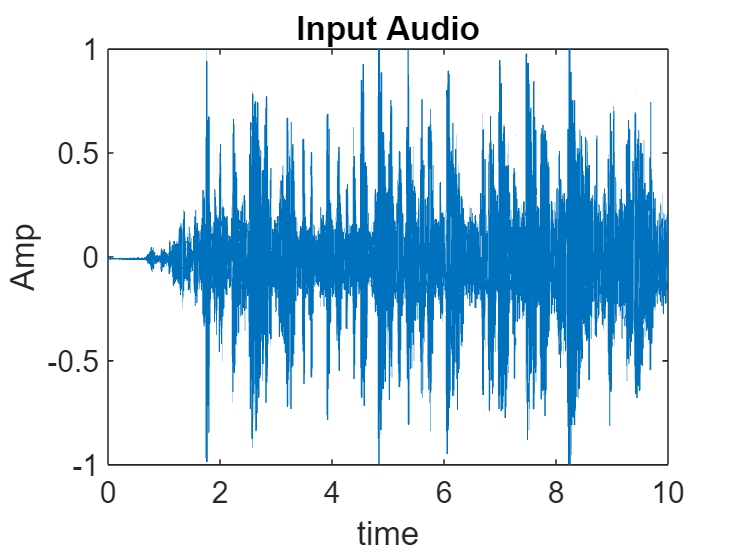

filename = 'listen-to-the-ancient-egyptions-tv.wav';
[y,Fs] = audioread(filename); 
t= 0:1/Fs:240000/Fs - 1/Fs;
figure;
plot(t, y);
title("Input Audio");
xlabel("time");
ylabel("Amp");

- % Reading audio file "Listen to the ancient egyptions tv.wav"

- %[y, Fs]: These are the output variables, y will contain the audio data, and Fs will store the sampling rate of the audio

## ***Reading Coefficients from text file***

file = fopen('filters.txt', 'r');
lines = cell(0, 1);

while ~feof(file)
    line = fgetl(file);
    lines = [lines; {line}];
end
lines = lines';
fclose(file);

flipped_lines = flip(lines);

coeff= [lines, flipped_lines(2:end)];
coeff= str2double(coeff);

%initalize filter bank 
fb = zeros(32,512);

for i= 0:1:31
    for j= 0:1:511
        fb(i+1,j+1)= coeff(j+1) * cos((i+0.5)*(j-16)*pi/32);
    end
end

- Reverse the order of the lines using the flip function, storing the result in flipped_lines

- Concatenate the original lines with the reversed flipped_lines (excluding the first element of flipped_lines to avoid duplication) into a 2D array called coef

- Convert the cell array of strings (coeff) to a numeric array using str2double

## ***Initializing Filter Bank***

fb = zeros(32,512);

for i= 0:1:31
    for j= 0:1:511
        fb(i+1,j+1)= coeff(j+1) * cos((i+0.5)*(j-16)*pi/32);
    end
end

-  Filter Bank Initialization

- Create a 32x512 matrix called fb and initialize all elements to zero

-  Using two nested loops to iterate over each element of the filter bank (fb)

-  Outer loop (i) ranges from 0 to 31

-  Inner loop (j) ranges from 0 to 511

-  Calculate the value for each element of the filter bank using the formula:

-  fb(i+1, j+1) = coeff(j+1) * cos((i+0.5) * (j-16) * pi/32)

## ***Downsampling***

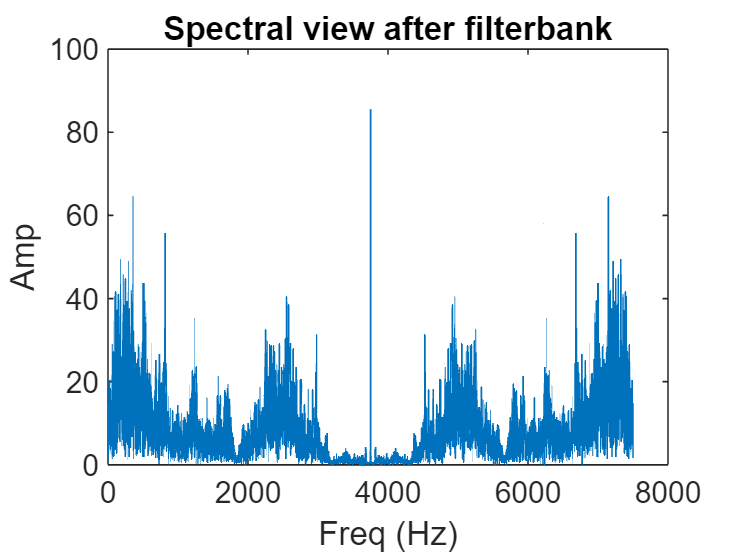

filter_bank = zeros(32, size(y, 1) / 32);

filtered_signal = [];
for i = 0:1:31
    % Filter the signal using the current filter
    filtered_seg = filter(fb(i+1,:), 1, y);
    downsampled_signal = downsample(filtered_seg, 32);
    filtered_signal = [filtered_signal downsampled_signal];
end

plot(abs(fftshift(fft(filtered_signal(:,1)))));
title("Spectral view after filterbank")
xlabel("Freq (Hz)")
ylabel("Amp");

-  Initialize a filter bank matrix (filter_bank) with dimensions 32x(size(y, 1)/32) and set it to zeros

-  Initialize an empty array (filtered_signal) to store the filtered signal

-  Loop through each filter in the filter bank (32 filters)

-  Filter the input signal (y) using the current filter (fb(i+1,:)) and store the result in filtered_seg

-  Downsample the filtered segment by a factor of 32 

-  Append the downsampled segment (downsampled_signal) to the filtered_signal array and save

# **Psychoacoustic Model **

## ***Computing SPL in each band and Applying Threshold in Quite ***

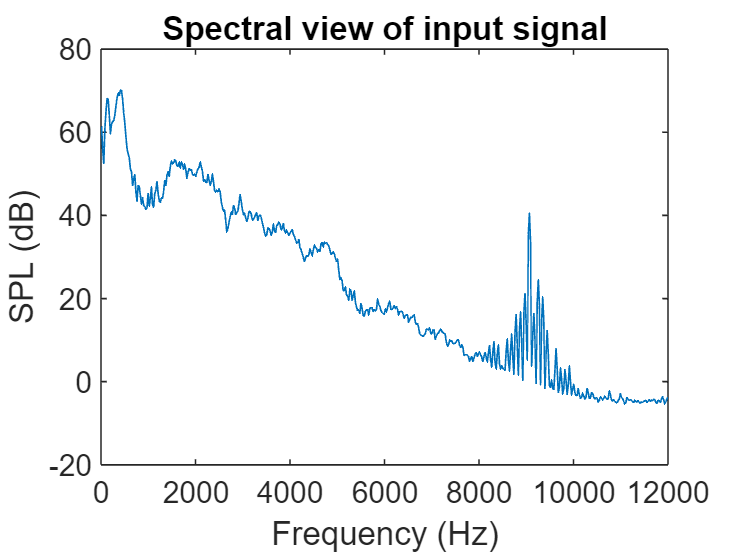

load('Signal_Spectrum.mat');

[x, y] = size(Signal_Spectrum);

Signal_Spectrum = Signal_Spectrum(:,513:end);
Fs = 24000;

F = linspace(-Fs/2, Fs/2, 1024);
F = F(:, 513:end);

SPL = [];
N = 1024;
for n = 1:N/2
    SPL_subband = 96 + 10*log10((4/(N^2))*abs(Signal_Spectrum(:, n)).^2*(8/3));
    SPL = [SPL SPL_subband];
end

plot (F, SPL);
title("Spectral view of input signal");
xlabel("Frequency (Hz)")
ylabel("SPL (dB)");



% % quit A
A = [];
for i = 1:N/2
   A_subband= (3.64*(F(:, i)/1000).^(-0.8))-(6.5 *exp((-0.6)*(F(:, i)/1000 -3.3).^2))+(10^(-3)*(F(:, i)/1000).^4);
   A = [A A_subband];
end

SPL(A > SPL) = 0;

- Load the previously saved filtered signal from the file 'filtered_signal.mat'

- Setting the sampling rate (`fs`) to 24000 Hz

- The number of samples and the number of subbands in the filtered signal are determined

- Initializing an array (`spl_values`) to store SPL values

- Initializing an empty array (`fft_result`) to store FFT results

- Computing 1024-FFT to each subband by looping in each subband of the filtered signal

- Then Extracting the signal for the current subband (`subband_signal`)

- Concatenate the FFT results for each subband into `fft_result`

- Calculating the SPL involves looping through each subband (n=1 to 32)

-  (SPL) in decibels using the formula:

- `96 + 10*log10((4/(n^2))*abs(fft_result(513:end, n)).^2*(8/3));`

- Concatenate the SPL values for each subband into `SPL`

- A is constructed as a threshhold with N/2 spectral lines to compare with SPL to conclude LK

- If SPL is less that the threshhold, SPL =0

## *Separation of Tonal & Non-Tonal Components, Maskers Decimation, and Masking Threshold per sub-band*

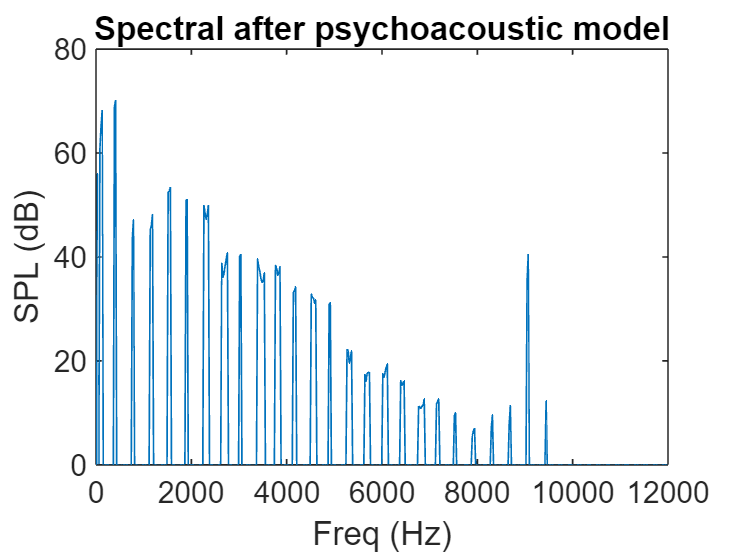

% divide into 32 sub frame 
% get global max and min using findpeaks 
maxs = [];
reshaped_SPL = [];
for i = 1:16:512
    [value, index] = findpeaks(SPL(:,i:i+15));
    local = [value ; index+i-1];
    maxs = [maxs local];
    reshaped_SPL = [reshaped_SPL ; SPL(:,i:i+15)];
end

[maxLength, maxSize] = size(maxs);

masked_ranges = [];
spl_values = [];
thresholds = [];
for i= 1:maxSize
    mask_range = masking_threshold(maxs(1,i), F(maxs(2,i)));
    spl_value = (3.64*(mask_range/1000).^(-0.8))-(6.5 *exp((-0.6)*(mask_range/1000 -3.3).^2))+(10^(-3)*(mask_range/1000).^4);
    masked_ranges = [masked_ranges mask_range];
    spl_values = [spl_values spl_value];
    line = polyfit([mask_range,maxs(1,i)],[spl_value,F(maxs(2,i))] ,1);
    line = line *1.5;
    %plot(polyval(line, 0:15));
    thresholds = [thresholds; polyval(line, 0:15)];
    subband = (fix(maxs(2,i)/16) +1);
    for j = rem(maxs(2,i),16)+1:16
        x = polyval(line, 0:15);
        if x(:, j) > reshaped_SPL(subband, j)
            reshaped_SPL(subband, j) = 0;
        end
    end
end

reshaped_SPL = reshape(reshaped_SPL.', 1,[]);

plot(F, reshaped_SPL);
title("Spectral after psychoacoustic model")
xlabel("Freq (Hz)");
ylabel("SPL (dB)")

- This loop iterates over the range 1 to 512 with a step size of 16. In each iteration, it processes a set of 16 subframes. This is achieved by the looping over the columns of the `SPL` matrix.

- For each set of 16 subframes, the `findpeaks` function is used to find peaks in the corresponding columns of the `SPL` matrix. The values and indices of these peaks are stored in the `local` array. The variable `local` effectively holds information about the peaks in the current set of subframes.

- For each peak found in the previous step, it calculates a `mask_range` using a function called `masking_threshold` , This function takes two arguments and returns a value.

- It calculates `spl_value` based on the calculated `mask_range`.

-  (`polyfit`) is performed between the mask range and the corresponding SPL value. The resulting line is scaled by a factor of 1.5.

- `polyval` for visualization

- The thresholds obtained from the fitted lines are stored in the `thresholds` array.

- It identifies the subband corresponding to the current peak.

- For each subframe in the subband, it compares the calculated threshold with the corresponding value in the reshaped SPL matrix. If the threshold is exceeded, the SPL value is set to 0.

## *Encoder*

fs = 24000; 

[numSamples, numSubbands] = size(filtered_signal);

spl_values = zeros(numSamples, numSubbands);

fft_result = [];
for subband = 1:numSubbands
    subband_signal = filtered_signal(:, subband);
    fft_result = [fft_result fft(subband_signal,1024)];
end

% Lk should be 512x32
SPL = [];
% convert fft to dB 
for n = 1:32
    SPL_subband = 96 + 10*log10((4/(n^2))*abs(fft_result(513:end, n)).^2*(8/3));
    SPL = [SPL SPL_subband];
end

reshaped_SPL = reshaped_SPL';

- FFT is performed on filtered signal

- SPL Computation

-  This section initializes the sampling frequency (`fs`) to 24000 Hz and determines the number of samples and subbands in the `filtered_signal` matrix.

- Each subband of the `filtered_signal` matrix through an FFT with a window size of 1024. The result is stored in the `fft_result` matrix.

- This loop calculates the (SPL) in decibels for each of the 32 subbands. It uses the formula to convert the magnitude of the FFT result to decibels. The resulting SPL values are stored in the `SPL` matrix.

% % Lk from psyhcho 1 vector 512 element 
% multiply element wise, result 512x32
x = [];
for i = 1:32
   x_value= reshaped_SPL.*SPL(:,i);
   x = [x x_value];
end
% 
% sum each column, so result 1x32 
sum_spl = sum(x,1);
% send to bit_allocation , number of bits 
subband_bits = zeros(1,32);
count = 0;
BPS_signal= 16;
if BPS_signal<=16
    BPS = BPS_signal;
else
    BPS = 16;
end

b = BPS;

for i=1:1:32
    [smax,index] = max(sum_spl);
    index;

    if count < 4
        b = BPS;
    elseif count<8
        if BPS - 10 >= 2 
            b = BPS - 10;
        else
            b = 2;
        end
    elseif count<12
        if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
        end
    elseif count<16
        if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
        end
    elseif count<20
       if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
       end
    elseif count<24
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 2;
        end
    elseif count<28
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 1;
        end
    else
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 1;
        end
    end
    subband_bits(index) = b;
    count = count + 1;
    sum_spl(index) = -inf;
end

- Bit Allocation:

- The first loop performs element-wise multiplication of the `reshaped_SPL` matrix with each column of the `SPL` matrix. The result is a matrix `x` with dimensions 512x32.

- (`sum_spl`) sums each column of the matrix `x`, resulting in a 1x32 vector, representing the sum of products for each subband.

- For the bit allocation loop, iterates over the 32 subbands, It then finds the subband with the maximum sum of products (`smax`), records its index, and allocates bits (`b`) based on certain conditions related to the value of `count`. The allocated bits for each subband are stored in the `subband_bits` array.

- If `count` is less than 4, set `b` to `BPS`.

- If `count` is between 4 and 7 (inclusive), set `b` to `BPS - 10` if the result is greater than or equal to 2, otherwise set `b` to 2.

- If `count` is between 8 and 11 (inclusive), set `b` to `BPS - 14` if the result is greater than or equal to 2, otherwise set `b` to 2, etc..

% send to quantizer number of bits and 12 sample from each 32 column then take the next 12 sample

quatized = zeros(7500,32);
maxi=zeros(625,32);
mini=zeros(625,32);
for j = 1 : 12 : 7500
    for i = 1 : 32
        [maxi((j-1)/12+1,i), mini((j-1)/12+1,i), quatized(j:j+11,i)]=Quan(filtered_signal(j:j+11,i), subband_bits(i));
    end
end

- Initialize three matrices: `quatized`, `maxi`, and `mini`. `quatized` will store the quantized values, while `maxi` and `mini` will store the maximum and minimum values for each set of 12 samples.

- The outer loop (`for j = 1:12:7500`) iterates over the samples, taking sets of 12 samples from each subband.

- The inner loop (`for i = 1:32`) iterates over the 32 subbands.

- Inside the inner loop, the function `Quan` is called to quantize the 12 samples from the current subband using the corresponding number of bits specified by `subband_bits(i)`. The quantized values are stored in `quatized`, and the maximum and minimum values are stored in `maxi` and `mini`, respectively.

## ***Decoder ***

restored_signal = zeros(240000, 32);
upsampled_subband = zeros(240000, 1);
fb = zeros (32,513);
dequatized_signal = zeros(7500, 32);

for i= 0:1:31
    for j= 0:1:512
        fb(i+1,j+1)= 32* coeff(j+1) * cos((i+0.5)*(j+16)*pi/32);
    end
end

fb = fb';

- Reconstructing the coefficients

- initialize matrices to store the reconstructed signal (`restored_signal`), upsampled subbands (`upsampled_subband`), the filter bank coefficients (`fb`), and the dequantized signal (`dequantized_signal`).

- loop constructs the filter bank (`fb`) by filling its elements based on a cosine modulation. The loop iterates through the rows and columns of `fb` and calculates the value for each element based on the cosine modulation. The resulting filter bank is then transposed (`fb = fb'`) to make it compatible with the later matrix multiplication.

for j = 1 : 12 : 7500
    for i = 1 : 32
        [dequatized_signal(j:j+11, i)]=DeQuan(maxi((j-1)/12+1,i), mini((j-1)/12+1,i), subband_bits(i), quatized(j:j+11,i));
    end
end

- dequantization step

- The outer loop (`for j = 1:12:7500`) iterates over the samples, taking sets of 12 samples from each subband.

- The inner loop (`for i = 1:32`) iterates over the 32 subbands.

- Inside the inner loop, the function `DeQuan` is called to dequantize the 12 samples from the current subband. The dequantized values are stored in the matrix `dequantized_signal`.

for i= 1:32
    upsampled_subband= upsample(dequatized_signal(:, i), 32);
    restored_signal(:,i) = filter(fb(:,i), 1, upsampled_subband);
end

- Upsampling step 

- The `upsample` function increases the sampling rate of the dequantized signal by a factor of 32.

- The `filter` function applies a filtering operation using the filter bank coefficients `fb(:, i)`

- The final result is stored in the `restored_signal` matrix, where each column represents a subband

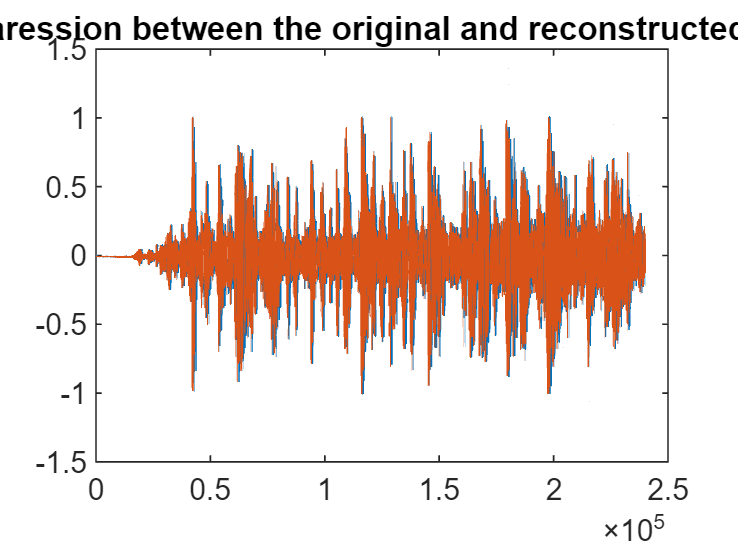

filename = 'listen-to-the-ancient-egyptions-tv.wav';
[y,Fs] = audioread(filename); 
reconstructed = sum(restored_signal, 2);
reconstructed = reconstructed';

plot([1:240000],reconstructed, [1:240000], y);
title("Comparession between the original and reconstructed signals")

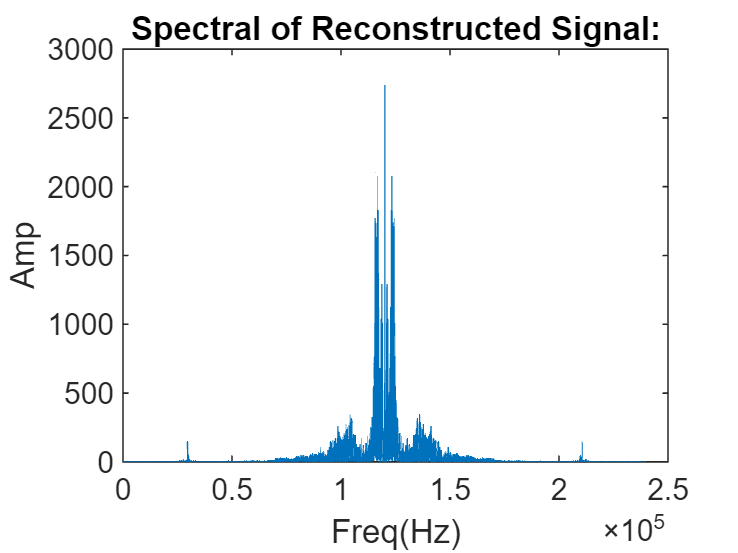




plot(abs(fftshift(fft(reconstructed))));
title("Spectral of Reconstructed Signal:");
xlabel("Freq(Hz)");
ylabel("Amp");

- Reconstructing Signal

- `sum(restored_signal, 2)`: This calculates the sum along the second dimension (columns) of the `restored_signal` matrix, summing up the contributions from all 32 subbands. This results in a column vector representing the reconstructed signal.

- `reconstructed = reconstructed'`: This transposes the reconstructed signal vector to make it compatible with the original signal.

- `plot([1:240000], reconstructed, [1:240000], y)`: This line plots both the original signal (`y`) and the reconstructed signal against the time axis.

## *Compression Ratio*

inputSignalSize = numel(y)*16;
encodedSignalSize = 0;

for i =1:32
    encodedSignalSize = encodedSignalSize + numel(quatized(:,i)*subband_bits(i));
end

compression_ratio = inputSignalSize / encodedSignalSize;

- The file result of the compression Ratio = 16

- 16 as a compression ratio is considered to be a decent ratio.